# ***Battery State of Charge Estimation using Extended Kalman Filter***

## Ghani Amri Rabbani, Ary Syahriar, Dwi Astharini, Haris Al-Qodri Maarif, Ahmad Husin Lubis, Danny Mokhammad Gandana

**Instructions for Downloading and Running the Script**

- Download raw datasets of Samsung battery from Mendeley Data page [https://data.mendeley.com/datasets/9xyvy2njj3/1](https://data.mendeley.com/datasets/9xyvy2njj3/1) 

- After downloading all the files including this one, unzip the file to a folder, do not modify the folder structure.

- Navigate to the folder with "DSP_EKF_SOC_Estimation.mlx" and "DSP_EKF_SOC_Graph.mlx".

- Open both files and run "DSP_EKF_SOC_Graph.mlx".

- The matlab script should run properly without any modification. If required, follow the comprehensive step-by-step in README file.

The main goal of this script is to provide a study of battery State of Charge (SOC) estimation using the Extended Kalman Filter (EKF) reinforced with digital signal processing (DSP) technique. The following script analyzes the battery's SOC and terminal voltage (Vt) during a driving cycle using a 2nd Order R-RC Equivalent Circuit Model considering the effects of battery surface temperature.

Each file in folder "Prepared Dataset" named in abbreviation of U.S. EPA driving cycle in order: HWFET, UDDS, and US06 which contain specific operating temperatures.

Run each driving cycle at the same operating ambient temperature to get a different results as shown in the paper. 

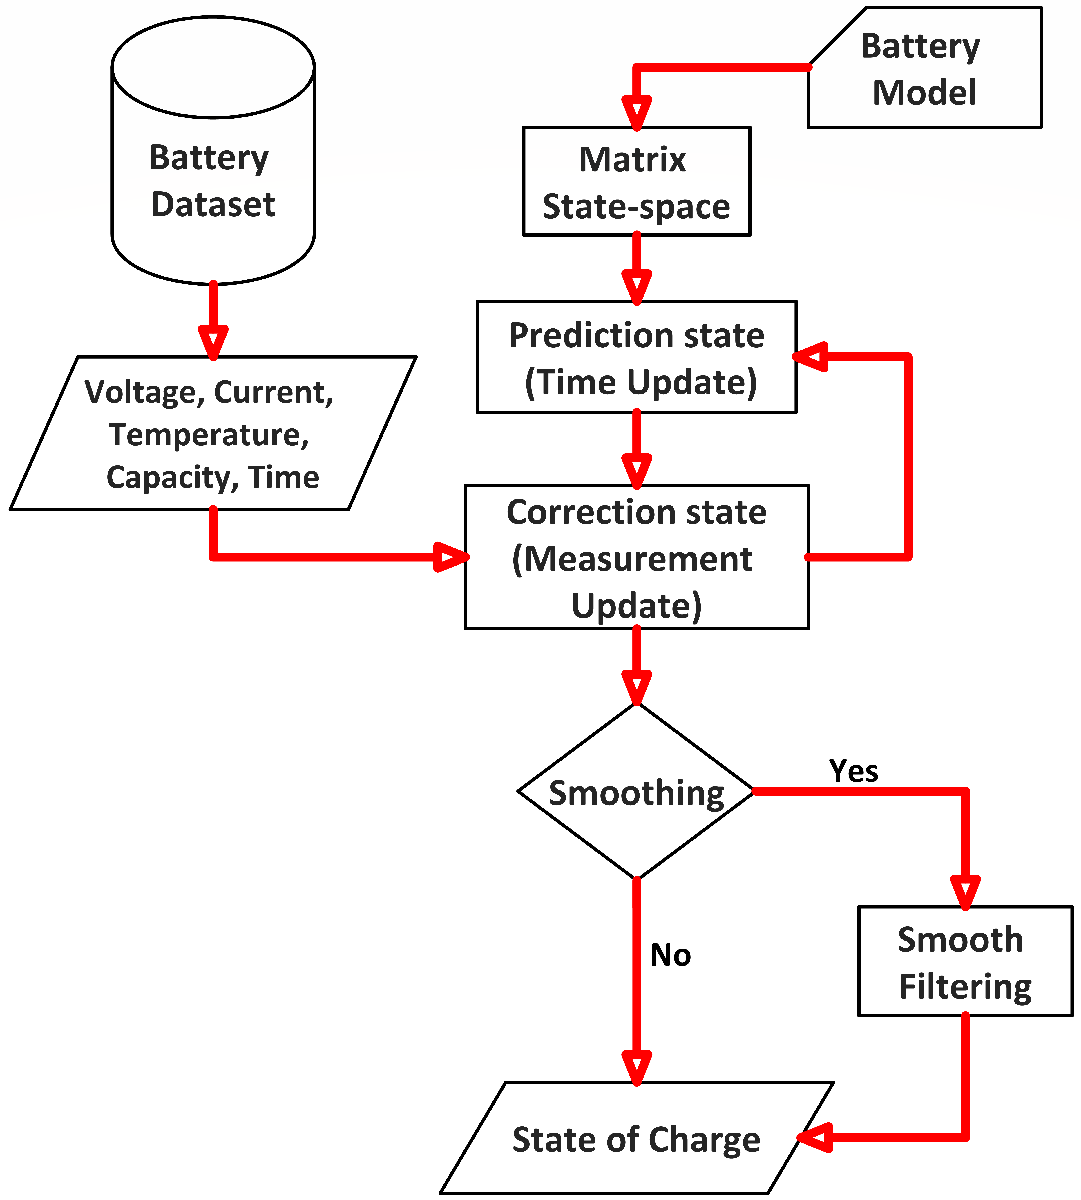

clc; clear; close all;

### Load Experimental Data

First, load the battery time, voltage, current, and temperature data of a driving cycle experiment. This will serve as an input into the EKF_SOC_Estimation function. Since the real SOC cannot be directly measured for comparison against the EKF estimated SOC, it is calculated using coloumb counting.

The battery manufacturer's nominal capacity can be used to calculate capacity. The nominal capacity used here should be the same as the variable $Cn$ in the EKF_SOC_Estimation function

load 'Battery Datasets\Pre-processed Dataset\Samsung_PreprocessedKalman.mat'

% Uncomment this lines to select HWFET driving cycle
LiIon.RecordingTime            = chop.B0_time_HWFET;
LiIon.Measured_Voltage         = chop.B0_volt_HWFET;
LiIon.Measured_Current         = chop.B0_curr_HWFET;
LiIon.Measured_Temperature     = chop.B0_temp_HWFET;

% Uncomment this lines to select UDDS driving cycle
%LiIon.RecordingTime            = chop.B25_time_UDDS;
%LiIon.Measured_Voltage         = chop.B25_volt_UDDS;
%LiIon.Measured_Current         = chop.B25_curr_UDDS;
%LiIon.Measured_Temperature     = chop.B25_temp_UDDS;

% Uncomment this lines to select US06 driving cycle
%LiIon.RecordingTime            = chop.B0_time_US06;
%LiIon.Measured_Voltage         = chop.B0_volt_US06;
%LiIon.Measured_Current         = chop.B0_curr_US06;
%LiIon.Measured_Temperature     = chop.B0_temp_US06;

% Uncomment this lines for specified the driving cycle
nominalCap                     = 3; % Battery capacity in Ampere-hour (Ah) taken from data.
LiIon.Measured_SOC             = ((nominalCap + chop.B0_Ah_HWFET).*100)./nominalCap;  % Calculate the SOC using Coloumb Counting for comparison
%LiIon.Measured_SOC             = ((nominalCap + chop.B25_Ah_UDDS).*100)./nominalCap;
%LiIon.Measured_SOC             = ((nominalCap + chop.B0_Ah_US06).*100)./nominalCap;

Depending on the data size, resampling may be needed to save computational time. In the following code lines, the data was resampled from 6 Hz to 1 Hz. The user may comment this part if desired.

LiIon.RecordingTime            = normalize(LiIon.RecordingTime, 'range'); % Normalize the dataset from 0 to 1.
LiIon.Measured_Voltage         = normalize(LiIon.Measured_Voltage, 'range'); % Normalize the dataset from 0 to 1.
LiIon.Measured_Current         = normalize(LiIon.Measured_Current, 'range'); % Normalize the dataset from 0 to 1.
LiIon.Measured_Temperature     = normalize(LiIon.Measured_Temperature, 'range'); % Normalize the dataset from 0 to 1.
LiIon.Measured_SOC             = normalize(LiIon.Measured_SOC, 'range'); % Normalize the dataset from 0 to 1.

**This script considers positive values of current as discharging currents, and negative as charging currents**. If the user's logged data has the opposite definition, then use the command in line 17 to reverse this definition, otherwise comment line 17. For plotting purposes, the sampling time is converted from seconds to hours.

% Current Definition: (+) Discharging, (-) Charging
LiIon.Measured_Current_R       = - LiIon.Measured_Current;

## EKF_SOC_Estimation Function

Given the measured current, voltage, SOC and temperature, the following function outputs the estimation of SOC and Vt, as well the errors with respect to the measurement.

[SOC_Estimated, Vt_Estimated, Vt_Error] = DSP_EKF_SOC_Estimation(LiIon.Measured_Current_R, LiIon.Measured_Voltage, LiIon.Measured_Temperature);

### Smooth Filtering Method

We standardize the data.... plus Gaussian filter and robust 

SOC_Estimated = normalize(SOC_Estimated,'range'); % Normalize the results from 0 to 1.
SOC_Estimated = smoothdata(SOC_Estimated,'gaussian',5000); %
SOC_Estimated = smoothdata(SOC_Estimated,'rloess','SmoothingFactor',0.9); %

### Plot the Results and Calculate Error

figure
subplot(2,1,1)
hold all
plot (LiIon.RecordingTime,(LiIon.Measured_SOC*100),"blue",'LineWidth',1.5)
plot (LiIon.RecordingTime,(SOC_Estimated*100),"red",'LineWidth',1.5)
legend('Coulomb Counting','Estimated EKF')
ylabel('SOC[%]')
xlabel('Time[second]')
title('SOC@0degC of HWFET Estimation')
grid on
subplot(2,1,2)
plot(LiIon.RecordingTime,(LiIon.Measured_SOC*100) - (SOC_Estimated*100),"black",'LineWidth',1.5);
legend('SOC Error');
ylabel('SOC Error [%]');
xlabel('Time[second]');
title('Error')
grid on

Calculate the root mean square error (RMSE) and the max error (MAX) of both the terminal voltage and SOC.

% Calculate RMSE and MAX of SOC
RMSE_SOC_HWFET_0deg_1    = sqrt((mean(((SOC_Estimated*100) - (Measured_SOC*100)).^2))); % (%)
RMSE_SOC_HWFET_0deg_2    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_HWFET_10deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_HWFET_25deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_HWFET_40deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_HWFET_n10deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_HWFET_n20deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)

%RMSE_SOC_UDDS_0deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_UDDS_10deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_UDDS_25deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_UDDS_40deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_UDDS_n10deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_UDDS_n20deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)

%RMSE_SOC_US06_0deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_US06_10deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_US06_25deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_US06_40deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_US06_n10deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)
%RMSE_SOC_US06_n20deg    = sqrt((mean(((Measured_SOC*100) - (SOC_Estimated*100)).^2))); % (%)

## Copyright Notice

This codes (inlcuding DSP_EKF_SOC_Estimation) is a modified version from from the original works of *State of Charge Estimation Function Based on Kalman Filter *by Fauzia Khanum, Eduardo Louback, Federico Duperly, Colleen Jenkins, Phillip Kollmeyer, Ali Emadi under BSD 3 Clause license. All right reserved.

## Reference

[1] Khanum, F. (2021, June 29). *State of charge estimation function based on Kalman filter*. File Exchange - MATLAB Central. [https://www.mathworks.com/matlabcentral/fileexchange/90381-state-of-charge-estimation-function-based-on-kalman-filter](https://www.mathworks.com/matlabcentral/fileexchange/90381-state-of-charge-estimation-function-based-on-kalman-filter) 

[2] Kollmeyer, Phillip. (2020, December 24). *Samsung INR21700 30T 3AH Li-Ion Battery Data*. Mendeley Data. [https://doi.org/10.17632/9xyvy2njj3.1](https://doi.org/10.17632/9xyvy2njj3.1) 

[3] *Mathworks smoothdata*. Smooth noisy data - MATLAB. (2023). [https://www.mathworks.com/help/matlab/ref/smoothdata.html](https://www.mathworks.com/help/matlab/ref/smoothdata.html) 